# Filtered Historical Value-at-Risk Forecasting

### Loading the data and selecting series

In this section, we are asked to perform this analysis for both the S&P 500 and the EUR/USD exchange rate. We will select the S&P 500 series since we already used this one in the previous exercise. Nevertheless, this can be easily changed bellow by selecting the EUR/USD series.

clear all
clc
% Downloading the SP500 data: 
fred_sp500 = fetch(fred(), 'SP500')

fred_sp500 = struct with fields:
                 Title: ' S&P 500'
              SeriesID: ' SP500'
                Source: ' S&P Dow Jones Indices LLC'
               Release: ' Standard & Poors (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily, Close'
                 Units: ' Index'
             DateRange: ' 2010-02-26 to 2020-02-25'
           LastUpdated: ' 2020-02-25 7:10 PM CST'
                 Notes: ' The observations for the S&P 500 represent the daily index value at market close.  The Federal Reserve Bank of St. Louis and S&P Dow Jones Indices LLC have reached a new agreement on the use of Standard & Poors and Dow Jones Averages series in FRED. FRED and its associated services will include 10 years of daily history for Standard & Poors and Dow Jones Averages series.  The S&P 500 is regarded as a gauge of the large cap U.S. equities market. The index includes 500 leading companies in leading industries of the U.S. econ

% Downloading the EUR/USD data:
fred_euro = fetch(fred(), 'DEXUSEU')

fred_euro = struct with fields:
                 Title: ' U.S. / Euro Foreign Exchange Rate'
              SeriesID: ' DEXUSEU'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.10 Foreign Exchange Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily'
                 Units: ' U.S. Dollars to One Euro'
             DateRange: ' 1999-01-04 to 2020-02-21'
           LastUpdated: ' 2020-02-24 3:49 PM CST'
                 Notes: ' Noon buying rates in New York City for cable transfers payable in foreign currencies.'
                  Data: [5515×2 double]


% Let's first get rid of the NaN values
fred_sp500.Data = fred_sp500.Data(~isnan(fred_sp500.Data(:,2)),:);
fred_euro.Data = fred_euro.Data(~isnan(fred_euro.Data(:,2)),:);
% Getting the vector with the relevant dates:
dates_sp = fred_sp500.Data(:,1);
dates_euro = fred_euro.Data(fred_euro.Data(:,1)>=dates_sp(1),1);
% Finally, getting sp500 and euro data for the last 10yrs:
sp500 = fred_sp500.Data(:,2);
euro = fred_euro.Data(fred_euro.Data(:,1)>=dates_sp(1), 2);

Now select the returns of which series we want to analyse:

% Selecting SP500:
r = diff(log(sp500))*100;
dates = dates_sp(2:end); 
% Selecting EUR/USD:
%r = diff(log(euro))*100;
%dates = dates_euro(2:end); 

## Exercise 73

Since we are asked to use a GARCH(1,1) model to construct filtered historical VaR forecasts, we need to first estimate this GARCH(1,1) model.

options.Display = 'none';
[~,~,ht] = tarch(r,1,0,1,[],[],[],options);

The next step is to use this estimated time-varying variance to normalize the vector of returns:

std_r = r ./ sqrt(ht);

### FHS VaR

The FHS VaR is simply the unconditional quantile at any point in time of the standardized returns, which is then scaled back by the forecast volatility. So let's build these FHS VaR forecasts!

% Data length and place holders
T = length(r);
FHS_forecast_05 = nan(T,1);
FHS_forecast_01 = nan(T,1);
% Iterate through the time series.  The forecast for t+1 is stored in t:
for t = ceil(T*.25):(T-1)
    % Scaling quantiles by the forecasted volatility:
    FHS_forecast_05(t) = sqrt(ht(t+1)) * quantile(std_r(1:t),.05);
    FHS_forecast_01(t) = sqrt(ht(t+1)) * quantile(std_r(1:t),.01);
end
% Finally storing these into a matrix:
FHS_VaR = [FHS_forecast_05 FHS_forecast_01];

### Plotting

This plot shows the returns, the FHS VaR and the HITs, which have been scaled to match the returns that caused the HIT. The non-HITs are removed from the graph by setting their values to NaN. 

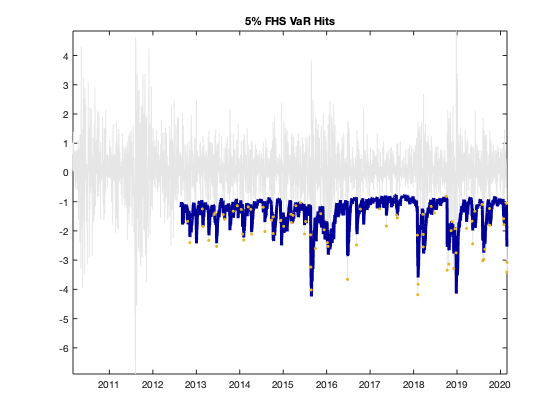

% 5% VaR
figure()
hit05 = r(2:end)<FHS_forecast_05(1:end-1);
scaled_hit = hit05.*r(2:end);
scaled_hit(~hit05) = nan;
h = plot(dates,r,dates,FHS_forecast_05,dates(2:end),scaled_hit);
set(h(1),'Color',[.9 .9 .9])
set(h(2),'Color',[.0 0 .6],'LineWidth',3)
set(h(3),'LineStyle','none','Marker','.')
title('5% FHS VaR Hits')
axis tight
datetick('x','keeplimits')

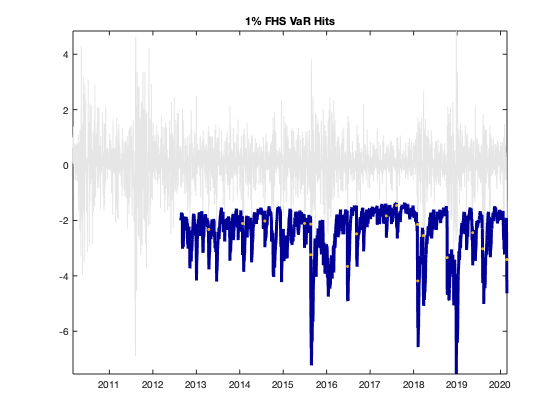

% 1% VaR
figure()
hit01 = r(2:end)<FHS_forecast_01(1:end-1);
scaled_hit = hit01.*r(2:end);
scaled_hit(~hit01) = nan;
h = plot(dates,r,dates,FHS_forecast_01,dates(2:end),scaled_hit);
set(h(1),'Color',[.9 .9 .9])
set(h(2),'Color',[0 0 .6],'LineWidth',3)
set(h(3),'LineStyle','none','Marker','.')
axis tight
title('1% FHS VaR Hits')
datetick('x','keeplimits')

Although not a formal test, these plots do a very good job in presenting the results from our filtered historical VaR forecasts. By doing the plots for both the SP&500 and the EUR/USD exchange rate, we see that the VaR forecasts are more stable with the exchange rate given the higher persistency in volatility in this series coming from the GARCH model. Overall, the influence of the GARCH variance estimates that are used to construct the filtered historical VaR generate forecasts that vary a lot more with time than the simple historical VaR. This makes sense once that the GARCH objective is exactly to capture the dynamics of this time-varying volatility.

To conclude, let's save the dataset with these filtered VaR forecasts. We will also save the returns and date series in the same data file so we don't need to, once more, fetch this data from the FRED. 

save FHS_VaR FHS_VaR r dates